%% Parameters
J  = 3e-2;      % inertia [kg*m^2]
Cw = 0.01;      % rotational damping [N*m*s/rad]
Ts = 0.0005;     % sample time [s] (2 ms)

s = tf('s');

%% Continuous inner plant: M -> w   ( w_dot = (-Cw*w + M)/J )
G_inner_c = 1/(J*s + Cw);

%% Discretize inner plant and outer integrator
G_inner = c2d(G_inner_c, Ts, 'zoh');       % M -> w (discrete)
G_phi   = c2d(1/s,         Ts, 'tustin');  % w -> phi (discrete integrator)

%% Tunable discrete PIDs (fixed Ts)
C_inner = tunablePID('C_inner','PID');  C_inner.Ts = Ts;  % rate PID
C_outer = tunablePID('C_outer','PID');  C_outer.Ts = Ts;  % angle PID

% Constraints
C_inner.Kp.Minimum = 0; C_inner.Ki.Minimum = 0; C_inner.Kd.Minimum = 0;
C_outer.Kp.Minimum = 0; C_outer.Ki.Minimum = 0; C_outer.Kd.Minimum = 0;


%% Name I/Os for interconnection
C_outer.InputName = 'e_phi';   C_outer.OutputName = 'w_ref';
% C_inner.InputName = 'e_w';     C_inner.OutputName = 'M';

% Controller outputs M_ctrl, not M (needed to sum with disturbance)
C_inner.InputName  = 'e_w';    C_inner.OutputName = 'M_ctrl';

% Plant input is M, output is w
G_inner.InputName = 'M';       G_inner.OutputName = 'w';
G_phi.InputName   = 'w';       G_phi.OutputName   = 'phi';

%% Summing junctions
Sum_w   = sumblk('e_w  = w_ref - w');
Sum_phi = sumblk('e_phi = phi_ref - phi');


% Disturbance summing junction (CONTROL + DISTURBANCE -> total M)
Sum_M    = sumblk('M = M_ctrl + M_dist');

%% Generalized closed-loop (phi_ref -> phi)
% Expose 'e_w','e_phi' (margins) AND 'w_ref','w' (inner tracking)
CL0 = connect(C_outer, C_inner, G_inner, G_phi, ...
              Sum_w, Sum_phi, Sum_M, ...
              'phi_ref','phi', ...
              {'e_w','e_phi','w_ref','w', 'M'}); % <-- expose M for effort goal


%% Tracking goals (separate for inner and outer)
tau_inner = 0.10/4;   % ~0.1 s settling for w_ref -> w  (fast)
tau_outer = 0.40/4;   % ~0.4 s settling for phi_ref -> phi (slower)

ReqTrackInner = TuningGoal.Tracking('w_ref','w',tau_inner);
ReqTrackOuter = TuningGoal.Tracking('phi_ref','phi',tau_outer);

%% Robustness goals (keep from your script)
ReqMi = TuningGoal.Margins('e_w',   6,45);   % inner margins
ReqMo = TuningGoal.Margins('e_phi', 6,45);   % outer margins

%% (Optional) keep overall angle tracking too, but it's redundant with ReqTrackOuter
% ReqTrackOverall = TuningGoal.Tracking('phi_ref','phi',1);

%% (Optional) cap control effort from inner loop to avoid insane M
% Max control gain from w_ref to M (ballpark – tune if needed)
ReqEffort = TuningGoal.Gain('w_ref','M', 50);

[CLtuned,fSoft] = systune(CL0, [ReqTrackInner, ReqTrackOuter, ReqMi, ReqMo, ReqEffort]);

Final: Soft = 1e+03, Hard = -Inf, Iterations = 21
       Some closed-loop poles are marginally stable (decay rate near 1e-07)


% [CLtuned,fSoft] = systune(CL0, [ReqTrackInner, ReqTrackOuter, ReqEffort]);

%% Show tuned PID gains
showTunable(CLtuned)

C_inner =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 0.197, Ki = 0.499, Kd = 0.000584, Tf = 1, Ts = 0.0005
 
Name: C_inner
Sample time: 0.0005 seconds
Discrete-time PIDF controller in parallel form.
-----------------------------------
C_outer =
 
              Ts               1     
  Kp + Ki * ------ + Kd * -----------
              z-1         Tf+Ts/(z-1)

  with Kp = 30.1, Ki = 0.0106, Kd = 3.55, Tf = 0.998, Ts = 0.0005
 
Name: C_outer
Sample time: 0.0005 seconds
Discrete-time PIDF controller in parallel form.



%% Closed-loop (no delay) transfer phi/phi_ref for plotting
T_noDelay = getIOTransfer(CLtuned,'phi_ref','phi');

%% Add ~5 ms delay in the angle measurement path (discrete N-sample delay)
Td     = 0.005;                    % 5 ms
Ndelay = max(1, round(Td/Ts));     % integer samples (5ms @ 2ms -> 3 samples)
DelayN = tf([zeros(1,Ndelay) 1], 1, Ts);  % z^(-N)

% Replace G_phi by Delay * G_phi and reconnect using tuned controllers
Ki = getBlockValue(CLtuned,'C_inner');  % numeric discrete PID
Ko = getBlockValue(CLtuned,'C_outer');
% Ki.InputName = 'e_w';    Ki.OutputName = 'M';
% Ko.InputName = 'e_phi';  Ko.OutputName = 'w_ref';

% Keep the SAME signal names used above
Ki.InputName = 'e_w';    Ki.OutputName = 'M_ctrl';
Ko.InputName = 'e_phi';  Ko.OutputName = 'w_ref';

G_phi_d = series(DelayN, G_phi);

G_phi_d.InputName = 'w'; G_phi_d.OutputName = 'phi';


CL_delay = connect(Ko, Ki, G_inner, G_phi_d, Sum_w, Sum_phi, Sum_M, ...
                   'phi_ref','phi');

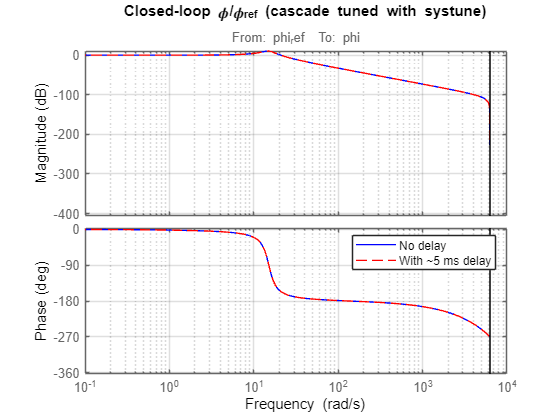

T_delay  = zpk(CL_delay);

%% Bode comparison (closed-loop angle response)
figure; bode(T_noDelay,'b', T_delay,'r--'); grid on;
legend('No delay','With ~5 ms delay');
title('Closed-loop \phi/\phi_{ref} (cascade tuned with systune)');

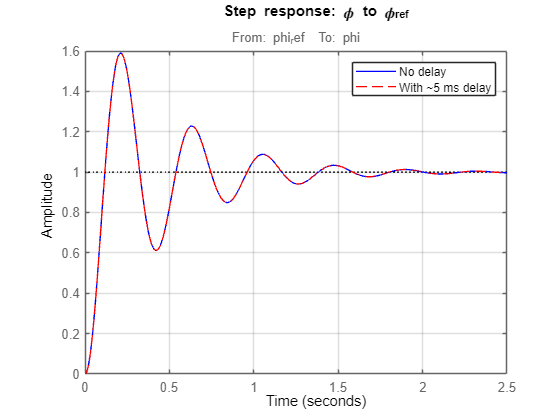


%% Step responses for intuition
figure; step(T_noDelay,'b', T_delay,'r--'); grid on;
legend('No delay','With ~5 ms delay');
title('Step response: \phi to \phi_{ref}');

%% Disturbance rejection model (explicit disturbance input)
% Disturbance as additive torque
CLd = connect(Ko, Ki, G_inner, G_phi, Sum_w, Sum_phi, Sum_M, ...
              {'phi_ref','M_dist'}, ...   % <-- inputs: reference and disturbance
              'phi');                     % <-- output: angle

% Inspect I/O names (optional sanity check)
CLd.InputName

ans = 2×1 cell array
    {'phi_ref'}
    {'M_dist' }


CLd.OutputName

ans = 1×1 cell array
    {'phi'}


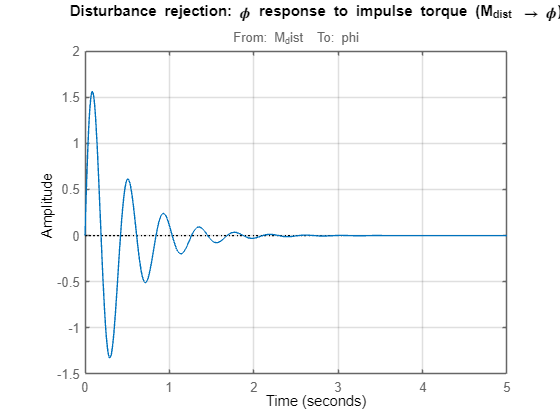

% SISO transfer from disturbance torque -> angle
Tmd = CLd('phi','M_dist');          % same as CLd({'phi'},{'M_dist'})

% Impulse disturbance response (e.g., 5 s)
figure; impulse(Tmd,5); grid on
title('Disturbance rejection: \phi response to impulse torque (M_{dist} \rightarrow \phi)')